### **Communication Systems Laboratory**

**Lab 4: OFDM Transmission Using USRP**

**Students: **B11901006 臧逸新、B11901013 俞柏安、B11901101 謝函蓁

#### Wifi-Modulation Initialize



clc; clear; close all;
global pilot_idx;
global data_idx;
global channel_est
global N_FFT;
global N_CP;
global fs;
global ts;
global fc;
%% Parameters
N_FFT = 64;  % FFT size
N_CP = 16;   % Cyclic prefix length
N_OFDM = N_FFT+N_CP; 
fs = 10e6;   % Sampling rate (Hz)
ts = 1/fs;   % Sampling time
fc = 915e6;  % Carrier frequency (Hz)
% Define subcarrier indices for 802.11a/g
pilot_idx = [8 22 44 58];   % Pilot subcarriers (1-based index)
data_idx = setdiff(1:N_FFT, [1:6, pilot_idx, N_FFT/2+1, 1:6, 60:64]); % Exclude DC, pilot, and unused guard bands


#### USRP initialze

#### **Funcion Definition**


% generate single OFDM symbol
function ofdm_SYM = ofdm_generate()
    %% Generate pilot tones (BPSK modulation)
    global pilot_idx;
    global data_idx;
    global N_FFT

    pilot_bits = randi([0 1], length(pilot_idx), 1) * 2 - 1; % BPSK mapping
    X_pilot = pilot_bits + 0j; % Convert to complex symbols
    
    %% Generate data tones (16-QAM modulation)
    data_bits = randi([0 3], length(data_idx), 1); % Random 16-QAM symbols
    qam_mod = qammod(data_bits, 4, 'UnitAveragePower', true);

    %% Create OFDM symbol in frequency domain
    ofdm_SYM = zeros(N_FFT, 1);
    ofdm_SYM(data_idx) = qam_mod;  % Assign 4-QAM data
    ofdm_SYM(pilot_idx) = X_pilot; % Assign BPSK pilot tones
end


function X_shifted = ofdm_shift(X)
    global N_FFT; global fs;
    freq_vector = (-N_FFT/2:N_FFT/2-1) * (fs/N_FFT); % Frequency in MHz
    fv = exp(-2*j*pi*(freq_vector)).';
    X_shifted = X .* fv;
end

% add time-domain cyclic prefix for a single symbol
function sig_b = ofdm_addCP(sig_a)
    global N_FFT; global N_CP;
    sig_b = zeros(N_FFT + N_CP, 1);
    cyclic_prefix = sig_a(N_FFT-N_CP+1:end);
    sig_b(1:N_CP) = cyclic_prefix;
    sig_b(N_CP+1:end) = sig_a;
end

% remove time-domain cyclic prefix for a single symbol
function sig_c = ofdm_removeCP(sig_b)
    global N_CP;
    sig_c = sig_b(N_CP+1:end);
end

% generate a complete normalized STS 
function STS = STS_generate()
    global N_FFT;
    STS_values = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, ...
                                0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 0, 0, 0, 0, ...
                                -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
                               0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
    
    single_STS = zeros(N_FFT, 1);
    single_STS(7:59) = STS_values;
    
    x_single_sts = ifft(ifftshift(ofdm_shift(single_STS)));
    
    STS = zeros(length(x_single_sts)*2.5, 1);
    STS(1:N_FFT/2) = x_single_sts(N_FFT/2+1:end);
    for i = 0:1
        STS(i*length(x_single_sts)+ N_FFT/2+1 : (i+1)*length(x_single_sts)+ N_FFT/2) = x_single_sts;
    end
    STS = STS / mean(abs(STS));
end

% generate a complete normalized LTS
function [LTS, single_LTS] = LTS_generate()
    global N_FFT;
    LTS_values = sqrt(13/6) * [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1, ...
        -1, -1, 1, 1, -1, 1,-1, 1,-1,-1,-1,-1,-1, 1, 1,-1,-1, 1,-1,1,-1,1,1,1,1];
    
    single_LTS = zeros(N_FFT, 1);
    single_LTS(7:59) = LTS_values;
    
    x_single_lts = ifft(ifftshift(ofdm_shift(single_LTS)));
    
    LTS = zeros(length(x_single_lts)*2.5, 1);
    LTS(1:N_FFT/2) = x_single_lts(N_FFT/2+1:end);
    for i = 0:1
        LTS(i*length(x_single_lts)+ N_FFT/2 +1 : (i+1)*length(x_single_lts)+ N_FFT/2 ) = x_single_lts;
    end
    LTS = LTS / mean(abs(LTS));
end

**(1)** Generate a frame with STS, LTS, and 5 OFDM symbols using 4-QAM modulation for the data tones. Pre-pad and post-pad the frame with 100 zeros (100 zeros, STS, LTS, 5 OFDM symbols, 100 zeros). Plot the generated frame in the time domain with the correct time unit in microseconds. Please mark the STS, LTS, and data symbols. Notice that the sampling rate of the USRP is 10 MHz, which is different from the sampling rate of 20 MHz in Lab 3, and thus the frame duration is different.

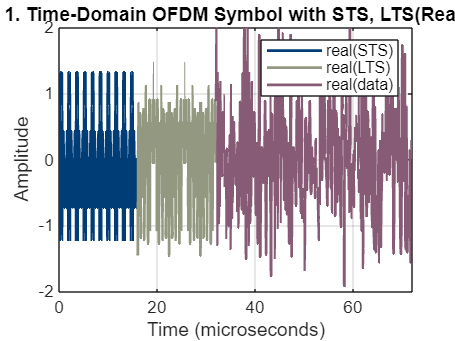

%% (1) Compute and plot magnitude spectrum
STS = STS_generate();
[LTS, single_LTS] = LTS_generate();


% 5- OFDM symbols with STS, LTS;
L_sig_5_head = length(STS) + length(LTS);
L_sig_5 =  L_sig_5_head + 5 * (N_OFDM);
sig_5 = zeros(L_sig_5, 1);

% pre-save data_bits
data_tx = zeros(5*48, 1);

% generate 5 OFDM Symbols
for i = 0:4
    X = ofdm_generate(); % generate single OFDM symbol
    X_shifted = ofdm_shift(X); 
    sig_a = ifft(ifftshift(X_shifted));
    x_cp = ofdm_addCP(sig_a);
    data_tx(48*i+1 : 48*(i+1)) = X(data_idx);
    sig_5(L_sig_5_head + i*(N_OFDM)+1 : L_sig_5_head+(i+1)*(N_OFDM)) = x_cp;
end
sig_5(L_sig_5_head+1:end) = sig_5(L_sig_5_head+1:end)/mean(abs(sig_5(L_sig_5_head+1:end)));

sig_5(1:length(STS)) = STS;
sig_5(length(STS)+1:length(STS)+length(LTS) )= LTS;
bits_tx = qamdemod(data_tx, 4, 'gray', OutputType='bit', UnitAveragePower=true);

time_vector = (0:L_sig_5-1) * ts * 1e6; % Time in microseconds

figure;
p1 = plot(time_vector(1:length(STS)), real(sig_5(1:length(STS))), 'Color', '#003C76', 'LineWidth', 1.5);
hold on;
p2 = plot(time_vector(length(STS)+1:L_sig_5_head), real(sig_5(length(STS)+1:L_sig_5_head) ),'Color', '#939880', 'LineWidth', 1.5);
p3 = plot(time_vector(L_sig_5_head+1:end), real(sig_5(L_sig_5_head+1:end)),'Color', '#875B75', 'LineWidth', 1.5);
xlabel('Time (microseconds)'); ylabel('Amplitude');
axis([0 72 -2 2])
title('1. Time-Domain OFDM Symbol with STS, LTS(Real)');
legend([p1(1), p2(1), p3(1)],'real(STS)', 'real(LTS)','real(data)');
grid on;
hold off;

(2) Transmit the frame generated in (1). Plot the received frame in the time domain with the correct time unit in microseconds. As in (1), please mark the STS, LTS, and data symbols. Please make sure the received signal is of proper signal strength – it should not show signs of clipping, and the signal can be easily distinguishable from the zeros. 

close all;
addpath("./test_code/")

padded_sig_5 = [zeros(100, 1); sig_5; zeros(100, 1)];
% todo: padded must be done in problem (1)

l = length(padded_sig_5);
[radio_Tx,radio_Rx] = USRP_init(l);
buffer = zeros(30*l, 1);
% buffer = zeros(30, l);

% Transmit the frame we generate
% tunderrun = radio_Tx(padded_sig_5);
% [rcvdSignal, ~, toverflow] = step(radio_Rx);
% buffer(1:l) = rcvdSignal;
% buffer(1,:) = rcvdSignal;

% Transmit 15 zero frames 
% (Otherwise there will be no output.) 
% (I not yet know why this bug happens.)
for ii = 1:15
    if ii == 1
        tunderrun = radio_Tx(padded_sig_5);
    else
        tunderrun = radio_Tx(zeros(l, 1));
    end
    % step(radio_Rx);
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+ii*l-l):(ii*l)) = rcvdSignal;
end

Error using comm.SDRuTransmitter/setupImplLocal
Radio with IP address '192.168.10.2' is not of the specified platform 'N200/N210/USRP2'.

Error in comm.internal.SDRuBase/setupImpl


% Keep reception for 15 frames 
for ii = 16 : 30
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer((1+ii*l-l):(ii*l)) = rcvdSignal;
end 

% To save new data, uncomment this line. 
% Otherwise, keep it commented so that rx_sig.mat won't be modified.
% save rx_sig.mat buffer

release(radio_Tx)
release(radio_Rx)

figure:

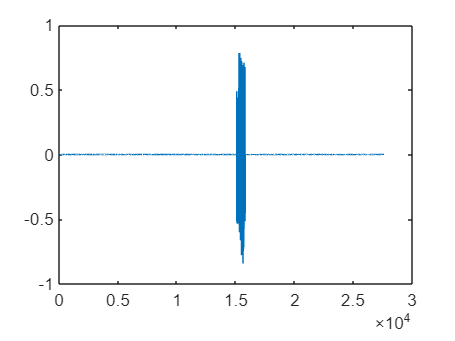

figure;
plot(real(buffer));
ylim([-1,1])

**(3) **Apply the frame synchronization algorithm you designed in Lab 3 to identify the correct beginning of the OFDM symbols. Please plot the match filter result.

**(4)** Based on the result, what index marks the beginning of the first long training symbols?

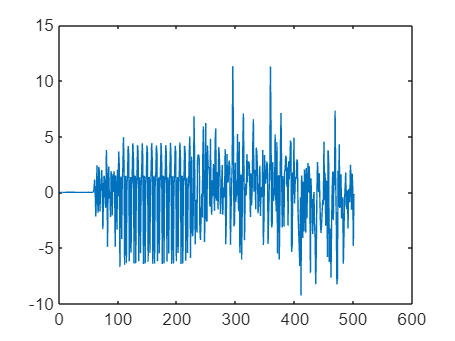

lts_start = 15295

ofdm_start = 15423

function [lts_start, ofdm_start] = LTS_CONV(buffer, sec_beg, sec_end, crit_lts, single_LTS)
    conv_sig_LTS = conv(buffer(1.5e4:1.55e4), single_LTS, "same"); % inden range should be adjusted
    plot(real(conv_sig_LTS))
    lts_peaks = find(conv_sig_LTS >= crit_lts);
    lts_start = sec_beg + lts_peaks(1);
    ofdm_start = lts_start + 2*64;
end

sec_beg = 1.5e4;
sec_end = 1.55e4;
crit_lts = 8;
[lts_start, ofdm_start] = LTS_CONV(buffer, sec_beg, sec_end, crit_lts, single_LTS)

**(5) **Transform the first long training symbol into the frequency domain and perform channel estimation. Plot the magnitude and phase of the channel across the subcarriers, from subcarrier index -26 to 26 (zero-subcarrier in the center).

function H_est = channel_est_2LTS(buffer, lts_start)
    LTS_values = sqrt(13/6) * [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1, ...
        -1, -1, 1, 1, -1, 1,-1, 1,-1,-1,-1,-1,-1, 1, 1,-1,-1, 1,-1,1,-1,1,1,1,1];

    LTS_val_new = [zeros(1, 6),LTS_values, zeros(1, 5)];

    lts_1 = buffer(lts_start : lts_start+64-1);
    lts_2 = buffer(lts_start+64 : lts_start+2*64-1);

    LTS_1_RX = fftshift(fft(lts_1));
    LTS_2_RX = fftshift(fft(lts_2));

    H1 = zeros(64, 1);
    H2 = zeros(64, 1);

    est_idx = [(-26+33 : -1+33) , (1+33 : 26+33)]; % -26 to 26 except '0'
    H1(est_idx) = LTS_1_RX(est_idx)./LTS_val_new(est_idx).';
    H2(est_idx) = LTS_2_RX(est_idx)./LTS_val_new(est_idx).';

    H_est = (H1 + H2) / 2;
end

H_est = channel_est_2LTS(buffer, lts_start);

Error using buffer
Not enough input arguments.


freq_vector = 915*1e6 + (-64/2:64/2-1) * (fs/64); % Frequency in MHz
figure; hold on;
s1 = stem(freq_vector/1e6, abs(H_est), 'Color', '#99755A', 'LineWidth', 1.5);hold on;

xlabel('Frequency (MHz)');
ylabel('Magnitude');
axis([910 920 0 8])
legend([s1(1)],'H\_est');
title('5. Channel Estimation using LTS');
grid on;

hold off;

**(7)** What frequencies do subcarriers -26, 0, and 26 correspond in this USRP transmission?

Ans: As defined in USRP_init.m, the center frequency of USRP is 915MHz = 0.915GHz = $f_0$.

Sub carrier spacing $\Delta f=\frac{f_s }{64}=156\ldotp 25\;\mathrm{kHz}$.

$f_{-26} =f_0 -\Delta f\cdot 26=910\ldotp 9375\;\mathrm{MHz}$.

$f_{26} =f_0 +\Delta f\cdot 26=919\ldotp 0625\;\mathrm{MHz}$.

**(8)** Find the samples corresponding to the OFDM symbols. Before equalization, plot the received constellation for data tones. What do you observe?

ofdm_rx_CP = reshape(...
    buffer(ofdm_start:(ofdm_start+(N_FFT+N_CP)*5)),...
    [], 5);

ofdm_rx = zeros(N_FFT, 5);

for ii = 1:5
    ofdm_rx(:,ii) = ofdm_removeCP(ofdm_rx_CP(:, ii));
end

plot(reshape(ofdm_rx(data_idx, :), 1, []));
xlabel("real part")
ylabel("imaginary part")
sgtitle("ofdm data before equalization")

**(9) **We skip the carrier frequency offset estimation and correction since we use the same USRP for transmission and reception in this experiment. Thus, without correcting carrier frequency offset, **equalize the OFDM symbols** using the estimated channel in (5) and (6) in the frequency domain. Plot the equalized received constellation for the data tones. Also, plot the transmitted constellation in the same figure for comparison. What do you observe?

ofdm_eq = zeros(N_FFT, 5);
est_idx = [(-26+33 : -1+33) , (1+33 : 26+33)]; % -26 to 26 except '0'

for ii = 1:5
    ofdm_eq(est_idx, ii) = ofdm_rx(est_idx, ii).*H_est;
end

plot(reshape(ofdm_rx(data_idx, :), 1, []));
hold on
plot(sig_5(L_sig_5_head+...
    reshape((N_CP+data_idx)'*(1:5), 1, [])))
hold off

xlabel("real part")
ylabel("imaginary part")
sgtitle("ofdm data before equalization")

**(10)** Use the samples of the 5 OFDM symbols for signal strength calculation, and use the padded zeros for noise calculation. What is the SNR of this received frame in dB?

**[Part 2] CFO Estimation and correction**

**(1)** Add a 5 ppm artificial CFO to the transmitted frame (with 100 OFDM symbols). Transmit and receive the frame using the same USRP. Estimate the channel using the two long training symbols. Plot the magnitude and phase of the estimated channel for both estimates across the subcarriers, from subcarrier index -26 to 26 (zero-subcarrier in the center). What do you observe?

function tx_sig_CFO = TX_CFO(sig, L)
    global ts;
    global fc;
    PPM = 5;
    delta_f_max = fc*PPM/1e6;
    
    t = (0:L-1) * ts;
    tx_sig_CFO = sig .* exp(1j*2*pi* delta_f_max *t);
end

tx_sig_CFO = TX_CFO(buffer, length(buffer));

% TODO: Transmit and receive Signal


% apply match filter to find where LTS starts, parameters to be tuned.
sec_beg = 1.5e4;
sec_end = 1.55e4;
crit_lts = 8;
[lts_start, ofdm_start] = LTS_CONV(buffer, sec_beg, sec_end, crit_lts, single_LTS)

%

H_est = channel_est_2LTS(buffer, lts_start);

freq_vector = 915*1e6 + (-64/2:64/2-1) * (fs/64); % Frequency in MHz
figure; hold on;
s1 = stem(freq_vector/1e6, abs(H_est), 'Color', '#99755A', 'LineWidth', 1.5);hold on;

xlabel('Frequency (MHz)');
ylabel('Magnitude');
axis([910 920 0 8])
legend([s1(1)],'H\_est');
title('5. Channel Estimation using LTS');
grid on;

hold off;